# **RT-QIBC analysis**

**Variables:**

YFP1 = mean Cdt1 IF intensity within nucleus

FarRed1 = mean Cdt1 IF intensity within nucleus

POI_time(:,3) = time since CRL4Cdt2 activation

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
%     'DMSO',2,3,1:9,[0 0 0]; %1
        'DMSO',2:7,2,1:9,[0 0 0]; %1      
        'DOX',2:7,3:11,1:9,[0 0 0]; %1    
    };

load([dataDir filesep 'C222_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};


**Set thresholds**

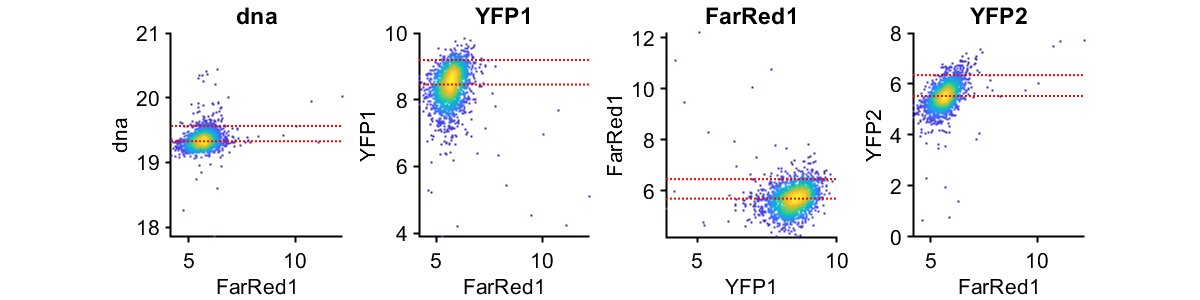

%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP1','FarRed1','YFP2'};
plotting = {'FarRed1','FarRed1','YFP1','FarRed1'};
prctiles = {[50 95], [50 95],[50 95],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 &...
        isnan(S(cond).POI(:,3));
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

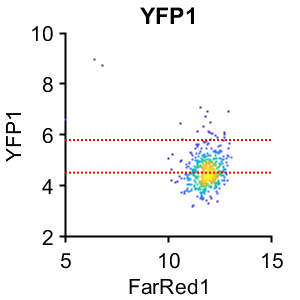


gates = {'YFP1'};
plotting = {'FarRed1'};
prctiles = {[50 95]};
figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 3 & S(cond).POI_time(:,3) > 1;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

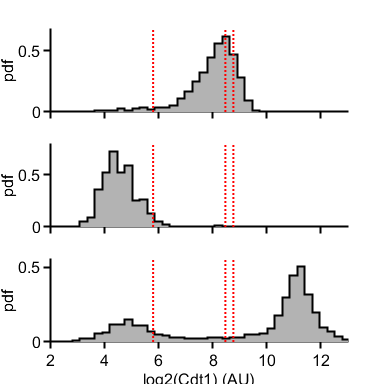

f = figure('units','inches','pos',[0 0 4 4]);
data = {};
cond = 1;
inds = S(cond).YFP1 > 2^2 & S(cond).YFP1 < 2^13 & S(cond).POI_time(:,1) < 4 & S(cond).POI_time(:,1) > 2 & isnan(S(cond).POI_time(:,3));
data =[ data real(log2(S(cond).YFP1(inds)))];

conds=[1 2];
for i=1:length(conds)
    condition = conds(i);
    inds = S(condition).POI_time(:,3) < 1 & S(condition).YFP1 > 2^2 & S(condition).YFP1 < 2^13;
    data = [data real(log2(S(condition).YFP1(inds)))];
end
trunc_thresh = 8;
% endo_thresh = prctile(data{1}(data{1} > trunc_thresh),75)
[p, xi] = ksdensity(data{1});
trunc_xi = xi(xi > trunc_thresh);
trunc_p = p(xi > trunc_thresh);
[~,i] = max(trunc_p);
endo_max = trunc_xi(i);
trun_data = data{1}(data{1} > endo_max);
endo_thresh = prctile(trun_data,(75 - 50)*2);
nhist(data,'samebins','pdf','noerror','separate','minx',2,'maxx',13,'LineWidth',1.5);

% set(gca,'FontSize',16)
ax = get(f,'children');
for i = 1:length(ax)
    axes(ax(i))
    xlim([2 13])
    vline(log2(gate.YFP1_S(2)))
        vline(endo_thresh)
        vline(endo_max)

    if i ~= 1
        set(gca,'xticklabel',{[]})
        %         set(gca,'xlabel','log2(Cdt1) (AU)')
    else
        
        xlabel('log2(Cdt1) (AU)')
        
    end
    
    
    
end

print_pdf([pwd() '\Figs\cdt1hist.pdf'])

**EdU levels early S**

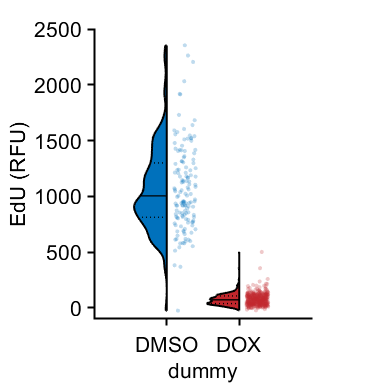

rng(1)
conds=[1 2];
poiAligned=3;
offset=0;

range = 4:.5:13;
timeGate = [0 .6];
midpoints = range + (range(2) -range(1))/2;
thresh = 2000;

f1 = figure;

gateVals = {{'FarRed1','YFP1'},{'FarRed1','YFP1'}};
% rangeVals = {{[0 Inf],[0 Inf]},{[0 Inf],[(2^endo_thresh)*4 (2^endo_thresh)*6]}};
rangeVals = {{[0 Inf],[0 Inf]},{[0 Inf],[(2^10) Inf]}};

ally = [];
group = [];
numb = 0;

data = {};
for i=1:length(conds)
    ind=~isnan(S(conds(i)).POI(:,poiAligned))& ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i});
    
%     tdata=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    tdata = S(conds(i)).POI_time(ind,poiAligned);
    gatedata=log2(S(conds(i)).YFP1(ind));
    ydata=(S(conds(i)).FarRed1(ind) - gate.FarRed1_G1(1)) ;
    wells = string(num2str(S(conds(i)).wellindex(ind,1:2)));
    
    %     if conds(i) == 4
    %         ydata = ydata + .75;
    %     end
    inds = tdata >= timeGate(1) & tdata <= timeGate(2);
    tdata = tdata(inds);
    ydata = ydata(inds);
    gatedata = gatedata(inds);
    wells = wells(inds);
    
    inds = randsample(length(ydata),min([length(ydata),400]), false);
        tdata = tdata(inds);
    ydata = ydata(inds);
    gatedata = gatedata(inds);
    wells = wells(inds);
    
    ally = [ally; ydata];
    group = [group; (numb+1)*ones(size(ydata))];
    numb = numb+1;
    
    data{i} = ydata;
end
colors = [[0 113 188; 193 39 45]/255];
cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = [colors(1,:); colors(2,:)];

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 10,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'EdU (RFU)'])
% xticks([1 3 5 7 9]+.5)
xticklabels({'DMSO','DOX'})
ylim([-100 2500])
% % axis square
pbaspect([.75 1 1])
% xtickangle(45)
xlabel('dummy')
print_pdf([pwd() '\Figs\cdt1_jitter_linear.pdf'])

meds = splitapply(@median,ally,group);
meds(1)/meds(2)

ans = 13.8917

nums = splitapply(@length,ally,group)

nums =    141
   400



bootstrap_med = cellfun(@(x) bootstrp(1000,@median,x),data,'UniformOutput',false);
DMSO = cell2mat(bootstrap_med(:,1)');
DOX = cell2mat(bootstrap_med(:,2)');
FCEdU = DMSO./DOX;
meanFC = mean(FCEdU,1)

meanFC = 13.9595

medFC = median(FCEdU)

medFC = 13.9084

prctile(FCEdU,[2.5 97.5])

ans =    12.4547   15.9061
